# EX. 3. 

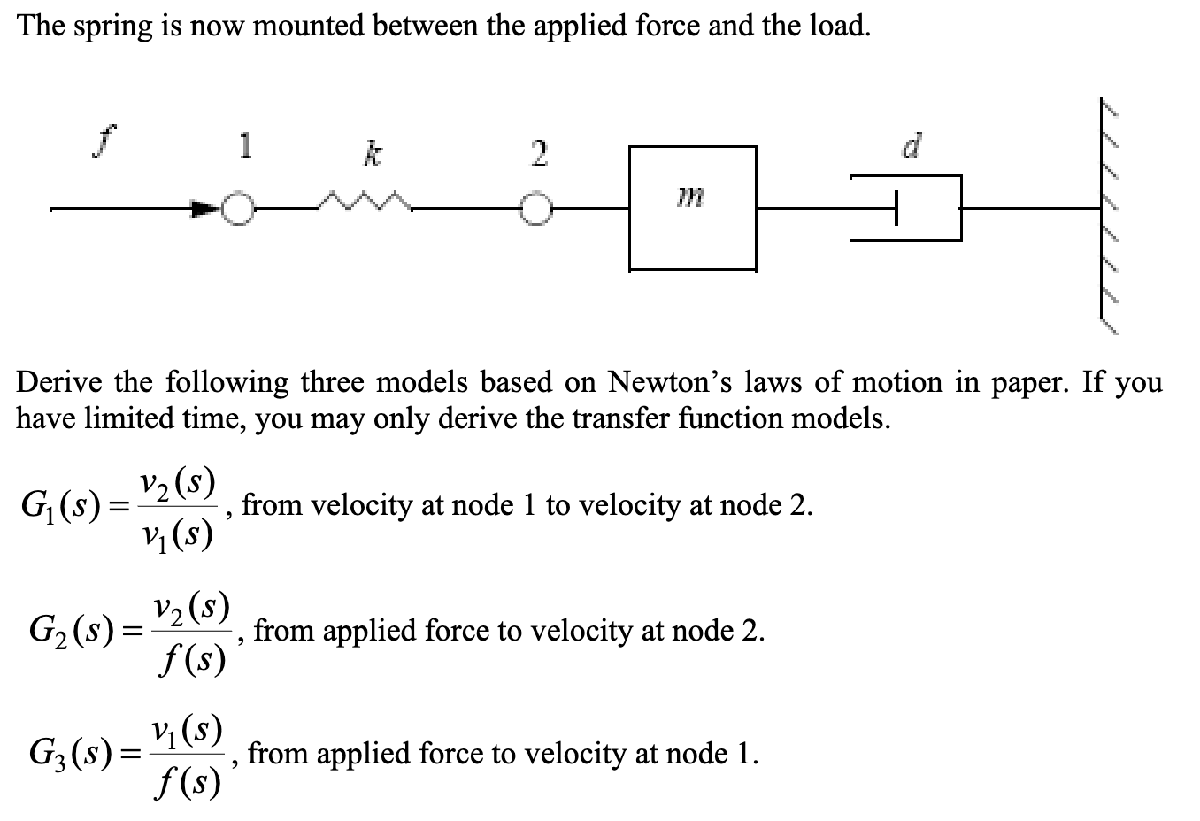

### Basic parameters

The basic parameters of the system are given in the problem description

m = 0.1; % kg
d = 0.5; % Ns/m
k = 8; % N/m


### Transfer function models

The transfer functions were derived on paper according to the following: 


$$G_1(s) = \frac{k}{ms^2 +ds + k}
$$



$$G_1(s) = \frac{s}{ms^2 +ds + k}
$$



$$G_1(s) = \frac{s}{k}
$$


% Derived transfer function model from velocity at node 1 to velocity at
% node 2

s = tf('s');

G1 = k / (m*s^2 + d*s + k);

% Derived transfer function model from force to velocity at node 2
G2 = s / (m*s^2 + d*s + k);

% Derived transfer function model from force to velocity at node 1
G3 = s/k;

### Step response from velocity at node 1 to velocity at node 2

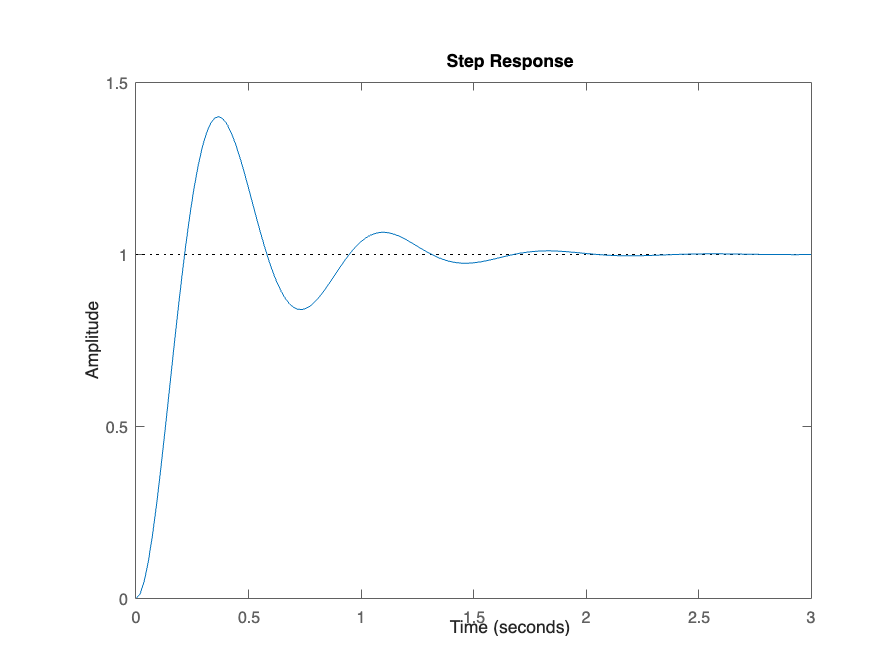

sp1 = stepplot(G1);

### Step response from force to velocity at node 2

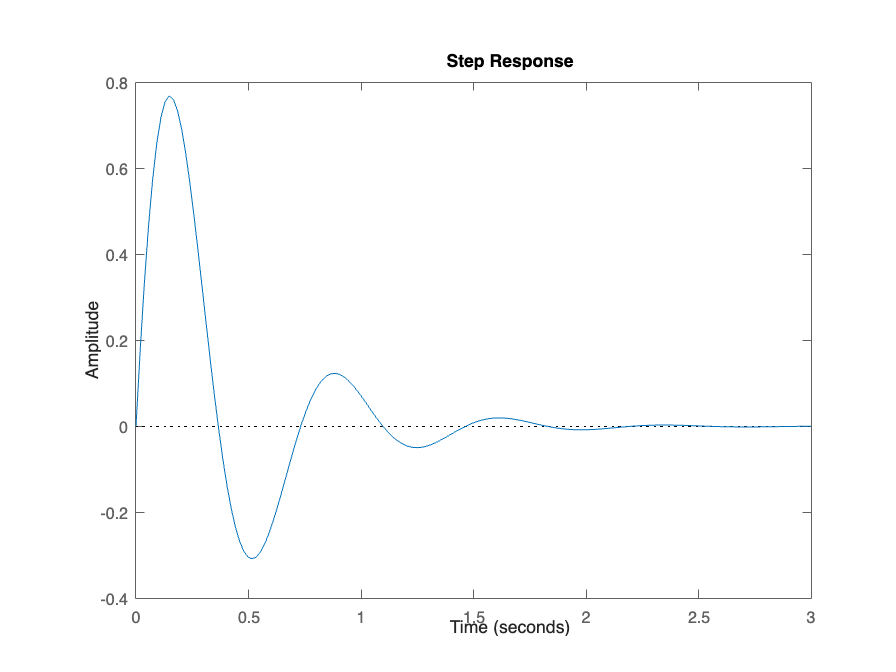

sp2 = stepplot(G2);

### Step response from force to velocity at node 1

G3 is an improper transfer function as the order of the numerator is higher than the order of the denominator

### Simulink and simscape models

model_name = 'Part1_new'; 
load_system(model_name);


set_param(model_name, 'StopTime', '2'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);



sim_time17 = simOut.tout;
output_signal17 = simOut.logsout.getElement('Velocity 1 Sim Ex.3').Values.Data; 


model_name = 'Part1_new'; 
load_system(model_name);


set_param(model_name, 'StopTime', '2'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval2'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval2'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave2'], 'Frequency', frequency); 
end


simOut = sim(model_name);



sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Velocity 2 Sim Ex.3').Values.Data; 


model_name = 'excercise1_3tf1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '2'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(20); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('velocity').Values.Data; 


figure;
%plot(sim_time22, output_signal22);
title(['System Position Response with ' input_type ' Input at 20 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
yval = output_signal12 - output_signal17;
plot(sim_time12, yval);
legend("Simulink transfer", "Simscape")

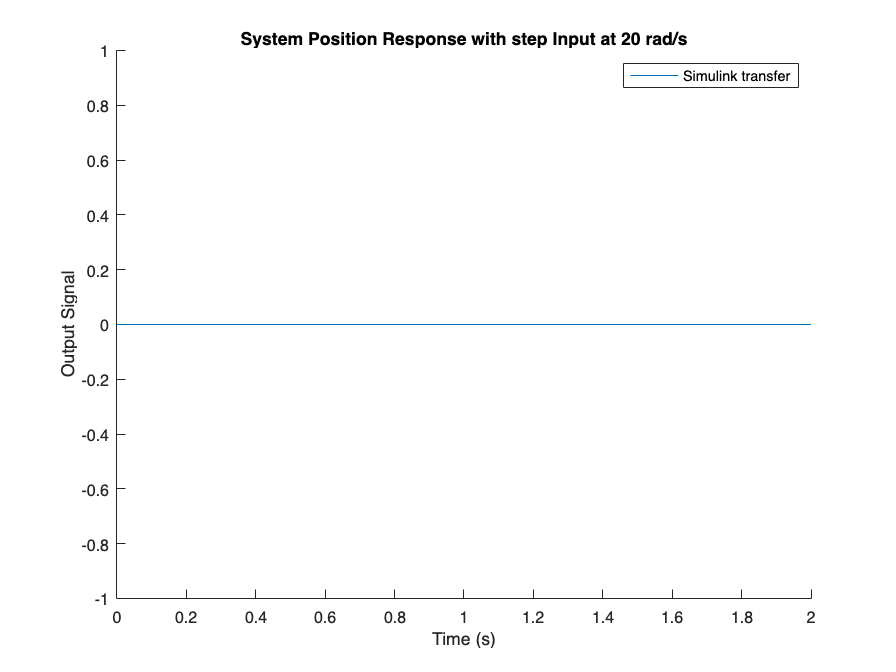

hold off